# MCT411 Project- Furuta Inverted Pendulum:

                                                                                           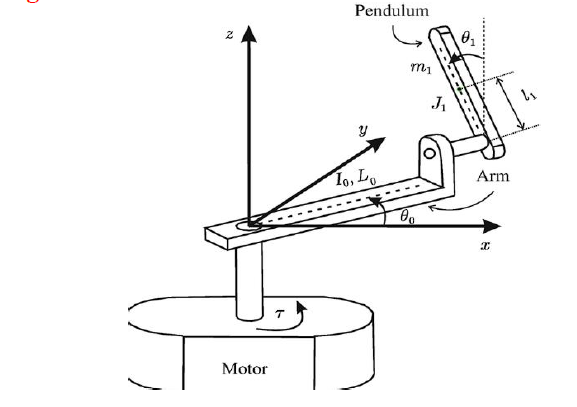

In this project we are doing the following:

1-Parameter Estimation to define all the unknown parameters of the used DC Motor

2-Build the system Model using state space representation

3-use LQR technique to control the pendulum Rod

# ***Motor Parameters***

motor_b = 3.27e-4;
motor_j = 3.55e-5;
motor_km = 0.0112;
motor_kt = 0.003;
motor_l = 0.0199;
motor_r = 9.3;
motor_efficiency = 0.5;
gear_box_effeciency = 0.9;
gear_box_ratio = 44;

# ***System Parameters***

m_pendulum= 0.015; %mass of pendulum
r=0.065;           %length of arm 
l=0.165/2;          %length of pendulum 

# ***Model Parameters***

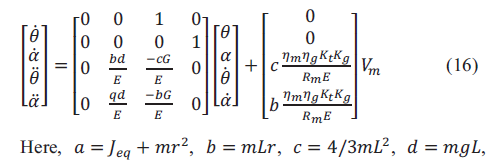

a=motor_j+(m_pendulum*r*r);
b=m_pendulum*l*r;
c=(4/3)*m_pendulum*l*l;
d=m_pendulum*9.8*l;

E=(a*c)-(b*b);
G = ((motor_efficiency*gear_box_effeciency*motor_km*motor_kt*(gear_box_ratio*gear_box_ratio))-(motor_b*motor_r))/(motor_r);

H= (motor_efficiency*gear_box_effeciency*motor_kt*gear_box_ratio)/(motor_r*E);

# ***State Space Representation:***

A_mat=[0 0 1 0;0 0 0 1;0 (b*d)/(E) (-(c*G)/E) 0 ; 0 ((a*d)/E) (-b*G)/E 0 ]; % system matrix
B_mat=[0;0;(c)*(H);(b)*(H)];                                                % input matrix  
C_mat=[1 0 0 0 ; 0 1 0 0];                                                  % output matrix
D_mat=[0;0];     

model=ss(A_mat,B_mat,C_mat,D_mat)

model =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3       0   139.6  -54.93       0
   x4       0   171.6  -32.46       0
 
  B = 
          u1
   x1      0
   x2      0
   x3  124.4
   x4  73.51
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



eig=(A_mat)

eig =          0         0    1.0000         0
         0         0         0    1.0000
         0  139.5740  -54.9349         0
         0  171.5664  -32.4615         0


rank(ctrb(A_mat,B_mat))

ans = 4

# ***LQR Parameters:***

Q=diag([75   800     400     70]);     
     %([Theta Alpha Theta_dot Alpha_dot])
R=1e-6;


K=lqr(A_mat,B_mat,Q,R);
k_theta=K(1)

k_theta = -8.6603e+03

k_alpha=K(2)    

k_alpha = 6.7409e+05

k_thetadot=K(3)

k_thetadot = -2.1851e+04

k_alphadot=K(4)

k_alphadot = 7.1843e+04

# ***System Response:***

lqr_sys=ss((A_mat-(B_mat*K)),B_mat,C_mat,0)

lqr_sys =
 
  A = 
               x1          x2          x3          x4
   x1           0           0           1           0
   x2           0           0           0           1
   x3   1.077e+06  -8.386e+07   2.718e+06  -8.937e+06
   x4   6.366e+05  -4.955e+07   1.606e+06  -5.281e+06
 
  B = 
          u1
   x1      0
   x2      0
   x3  124.4
   x4  73.51
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


Transferfn=tf(lqr_sys)

Transferfn =
 
  From input to output...
                  124.4 s^2 + 1.258e-07 s - 1.108e04
   1:  ---------------------------------------------------------
       s^4 + 2.563e06 s^3 + 4.847e07 s^2 + 2.422e08 s + 9.598e07
 
                  73.51 s^2 + 4.601e-08 s + 6.363e-09
   2:  ---------------------------------------------------------
       s^4 + 2.563e06 s^3 + 4.847e07 s^2 + 2.422e08 s + 9.598e07
 
Continuous-time transfer function.


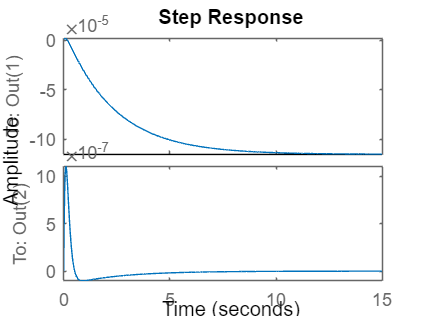

step(Transferfn)